# Task 1: MATLAB Image Analysis

## a)  Blob detection and boundary plotting  

In the GearsAndWashers.tif image:

- Put a boundary on each of the object and a number label identifying them.  

- Print the properties (mean intensity, area, perimeter, centroid, diameter) of each of the object.

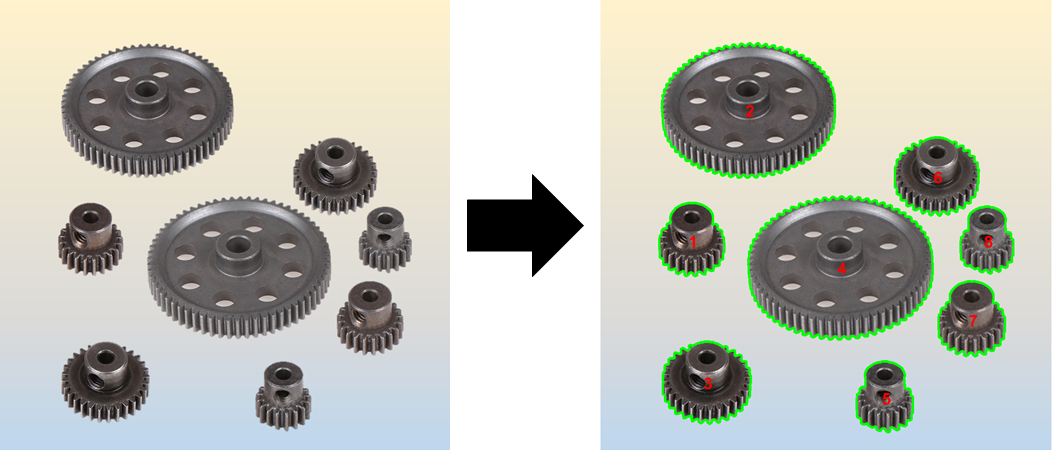

i.  Convert the image to a clean binary image with no holes by thresholding and `imfill` function.

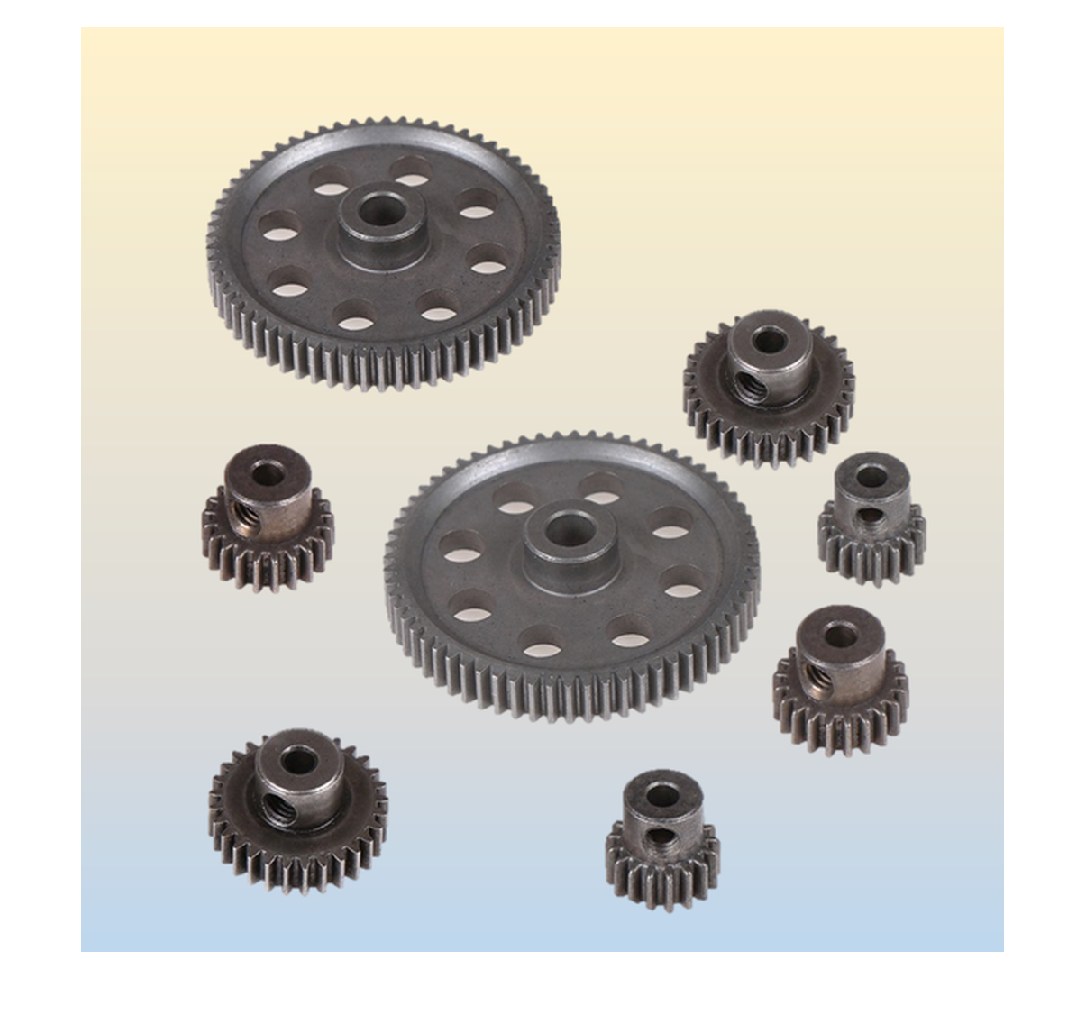

% Read and show the original image.
orig_gears = imread("Gears.tif");
imshow(orig_gears)

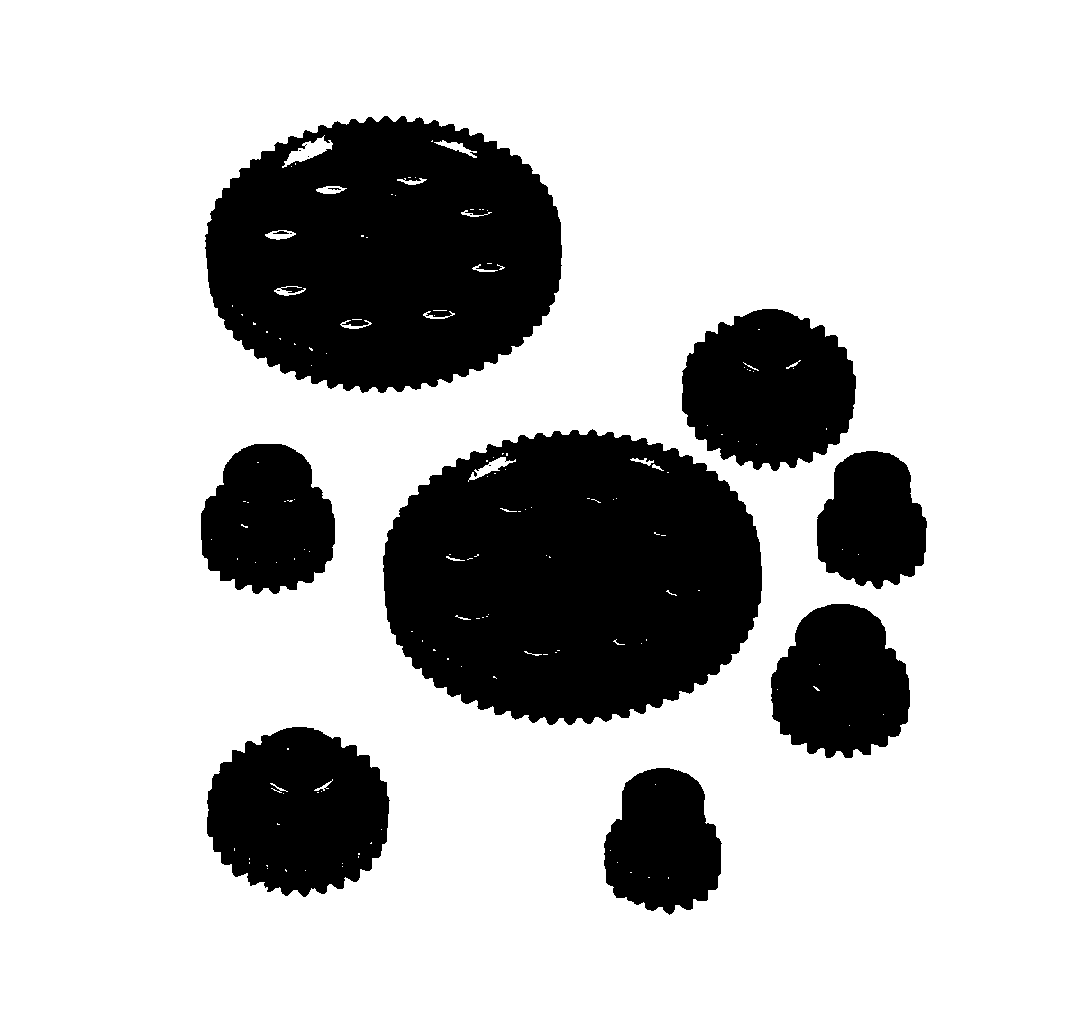

    % Use a threshold value to convert from grayscale to a binary image and 
    % show the resulting image.
    threshold = 0.8;
    grey_gears = im2bw(orig_gears, threshold);
    imshow(grey_gears);

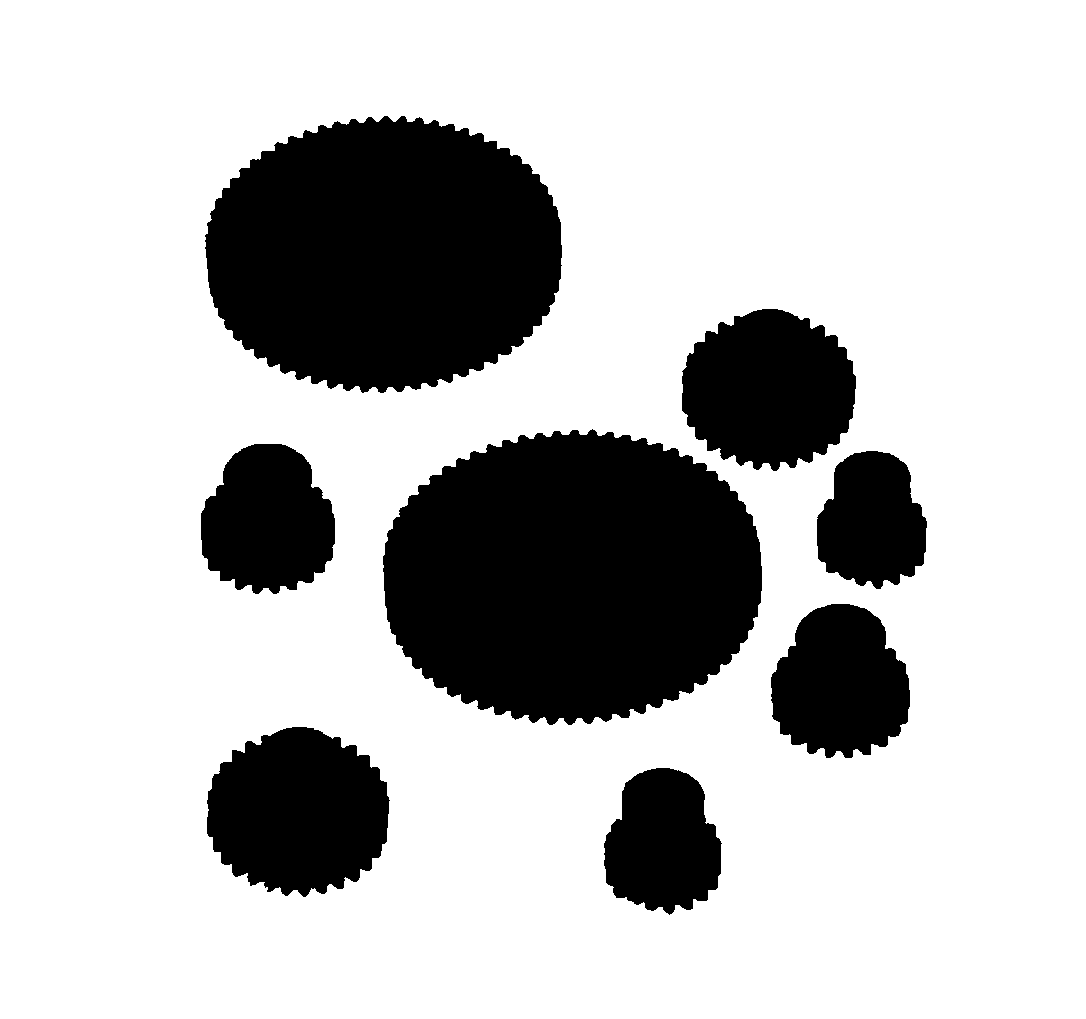

    % Perform  a "hole fill" to get rid of holes in the gears and any background pixels 
    % inside the blobs and show the resulting image.
    %gear_flipped = imcomplement(grey_gears);
    gear_filled = imfill(~grey_gears, 'holes');
    %gear_filled = imcomplement(gear_filled_flipped);
    imshow(~gear_filled)

ii.  Use the `bwlabel` command to generate a labeled image showing each of the blobs in the image.    

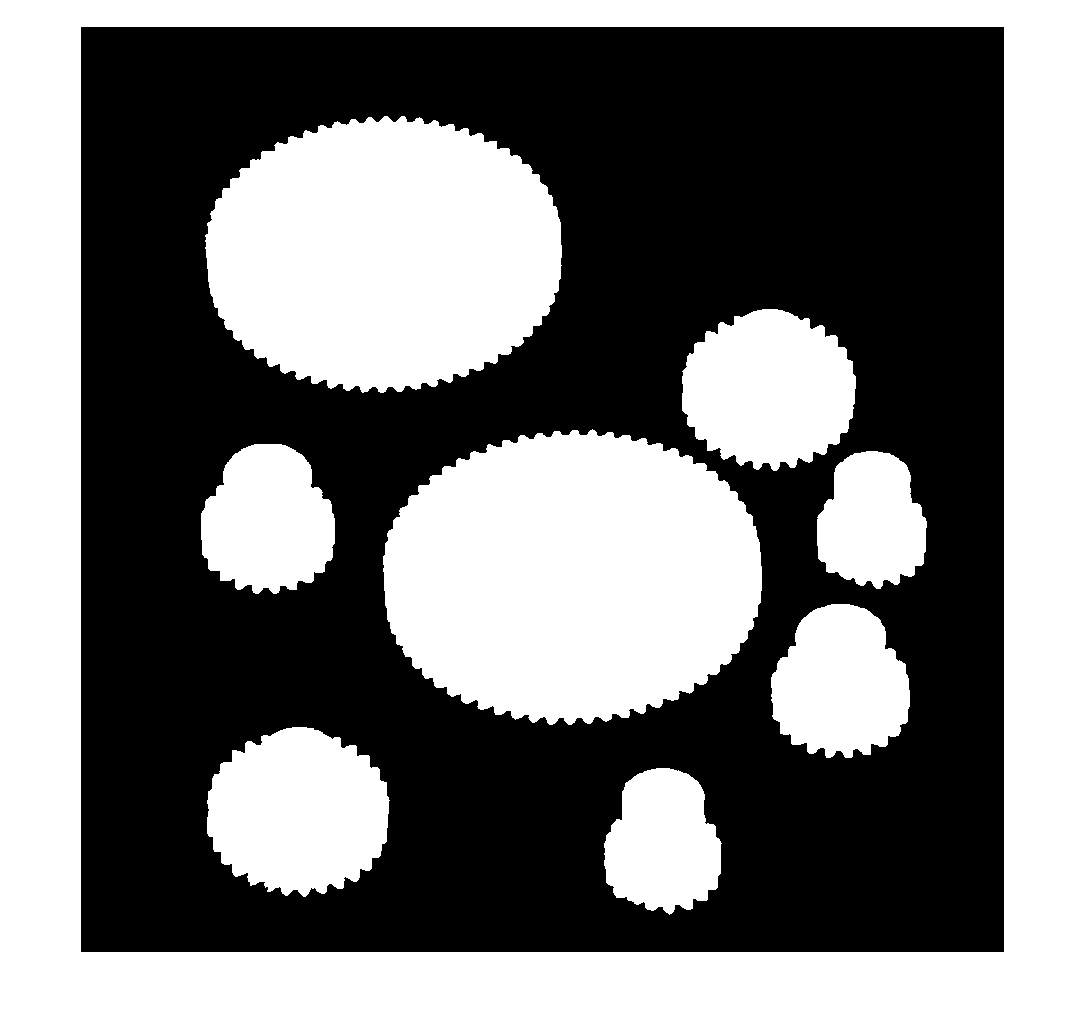

% Label blobs in the image and show the resulting image.
[labeledImage, numBlobs] = bwlabel(gear_filled);

imshow(labeledImage)

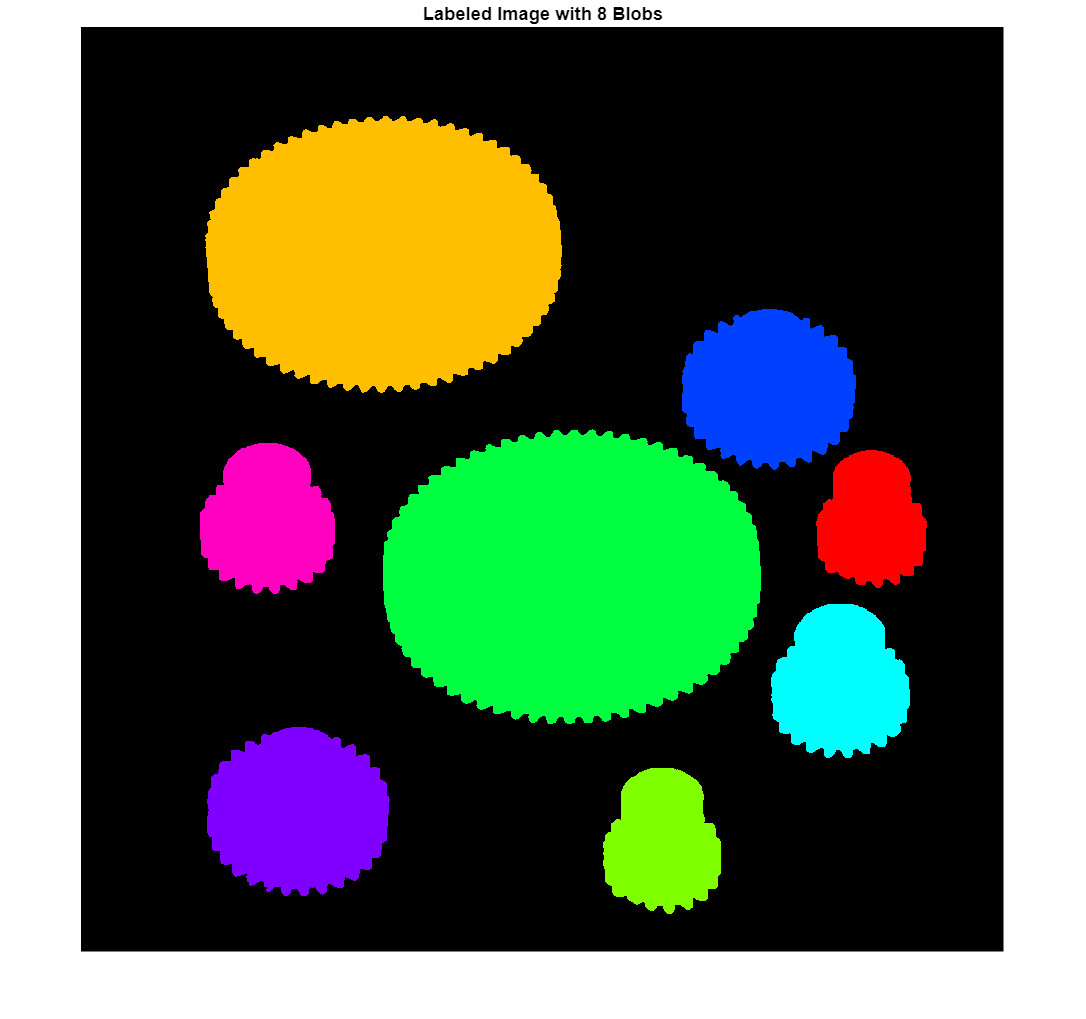

% Show labels in pseudo random colors.

colormap = rand(numBlobs, 3);
NumGears = label2rgb(labeledImage, 'hsv', 'k', 'shuffle');
imshow(NumGears)
title(['Labeled Image with ', num2str(numBlobs), ' Blobs']);

xlim([1 1025])
ylim([1 1027])

iii.  Use the `regionprops` command to get the nbwer of blobs found and the properties of each of the blobs.

% Get the number and properties of blobs found.

blobregions = regionprops(labeledImage, orig_gears, 'Area', 'Perimeter', 'Centroid', 'EquivDiameter', 'MeanIntensity')

Error using assert
Size of I doesn't match size information found in the first input argument.

Error in iptassert (line 19)
    assert(cond, message(msgID))

Error in regionprops>ParseInputs (line 1435)
    iptassert(isequal(sizeImage,size(I)), ...

Error in <a h

iv.  Use the `bwboundaries` command to plot the boundary of each of the blobs found on the original grayscale image to highlight the objects.

% bwboundaries returns a cell array where each cell contains the 
% row/column coordinates for an object in the image.

gearBoundries = bwboundaries(labeledImage)

% Plot the borders of all the objects on the original grayscale image 
% using the coordinates returned by bwboundaries.

figure;
imshow(orig_gears);
title('Original Picture w/ Borders');

hold on;

for k = 1:length(gearBoundries)
    boundary = gearBoundries{k};
    plot(boundary(:, 2), boundary(:, 1), 'g', 'LineWidth', 2);
end

hold off;


v.  Print the blob properties (mean intensity, area, perimeter, centroid, diameter) of each blob found and plot blob number labels on the objects in the outlined grayscale image.

% Printing out the properties of each blob

%creating the table to print values to 
properties = cell(numel(blobregions), 6);
for i = 1:numel(blobregions)
    properties{i, 1} = i;
    properties{i, 2} = (blobregions(i).Area);
    properties{i, 3} = (blobregions(i).Perimeter);
    properties{i, 4} = blobregions(i).Centroid(1); blobregions(i).Centroid(2);
    properties{i, 5} = (blobregions(i).EquivDiameter);
    properties{i, 6} = blobregions(i).MeanIntensity;
    % Calculating Mean Intensity
end

propTable = cell2table(properties, 'VariableNames', {'Blob Num', 'Area', 'Perimeter', 'Centroid', 'Diameter', 'Mean Intensity'});
disp(propTable)
% Put the blob number labels on the boundaries grayscale image.
figure;
imshow(orig_gears);
title('Original Picture w/ Borders and Gear Numbers');

hold on;

for k = 1:length(gearBoundries)
    boundary = gearBoundries{k};
    plot(boundary(:, 2), boundary(:, 1), 'g', 'LineWidth', 2);
end

hold on
for i = 1:numel(blobregions)
    text(blobregions(i).Centroid(1), blobregions(i).Centroid(2), num2str(i), 'Color', 'Red', 'FontSize', 20);
end
hold off

##    b)	  Find the different object types in the image

Identify the different object types (large gears, medium-large gears, medium-small gears, and small gears) in the image using the blob properties obtained in part (a) and extract them in separate images. 

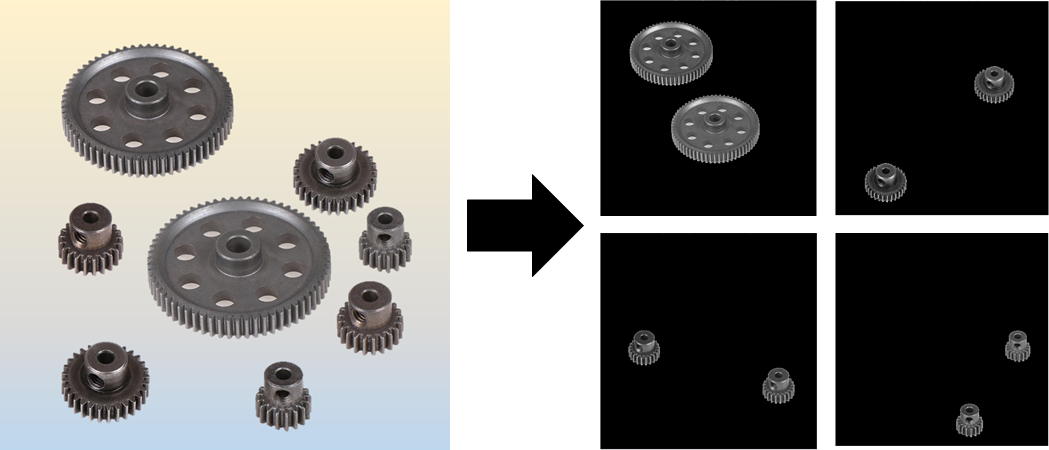

i.  Check blob properties from part (a) and identify which criteria to use to separate the four different types of the objects. 

% Check criteria of blob properties from part(a)(v) to select the best one to 
% separate object types

%Can I just assume to use Area seeing as the image we're using isn't
%changing for now? 


ii.  Use the `ismember` function to extract the selected blobs in the labeled image that was generated in part (a) using the `bwlabel` command.   Create a binary mask from the labeled image and filter each type of the object for display in the original grayscale image.

% Extract large gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.
blobArea = regionprops(labeledImage, 'Area');

minAreaBig = 95000;
maxAreaBig = 110000;

ValidBlobsBig = [blobArea.Area] >= minAreaBig & [blobArea.Area] <= maxAreaBig;
validLabelsForBig = find(ValidBlobsBig)

binaryMaskBig = ismember(labeledImage, validLabelsForBig);

figure;
imshow(binaryMaskBig);
title('Binary Mask for Large Gears');

% Use the binary image mask to filter out the large gears from the grayscale image 
% and show the original image with only the separated gears.

% Big Gears
gearImageBig = orig_gears .* uint8(binaryMaskBig);

figure;
imshow(gearImageBig)
title('Isolated Large Gears');


% Extract medium-large gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.

%Med-Big Gears

minAreaMedBig = 26000;
maxAreaMedBig = 30000;
ValidBlobsMedBig = [blobArea.Area] >= minAreaMedBig & [blobArea.Area] <= maxAreaMedBig;
validLabelsForMedBig = find(ValidBlobsMedBig)

binaryMaskMedBig = ismember(labeledImage, validLabelsForMedBig);

figure;
imshow(binaryMaskMedBig);
title('Binary Mask for Medium-Large Gears');

% Use the binary image mask to filter out the medium-large gears from the grayscale image 
% and show the original image with only the separated gears.

gearImageMedBig = orig_gears .* uint8(binaryMaskMedBig);

figure;
imshow(gearImageMedBig)
title('Isolated Medium-Large Gears');

% Extract medium-small gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.

% Med-Small Gears

minAreaMedSmall = 18500;
maxAreaMedSmall = 20000;
ValidBlobsMedSmall = [blobArea.Area] >= minAreaMedSmall & [blobArea.Area] <= maxAreaMedSmall;
validLabelsForMedSmall = find(ValidBlobsMedSmall)
binaryMaskMedSmall = ismember(labeledImage, validLabelsForMedSmall);

figure;
imshow(binaryMaskMedSmall);
title('Binary Mask for Medium-Small Gears');

% Use the binary image mask to filter out the medium-small gears from the grayscale image 
% and show the original image with only the separated gears.

gearImageMedSmall = orig_gears .* uint8(binaryMaskMedSmall);

figure;
imshow(gearImageMedSmall)
title('Isolated Medium-Small Gears');

% Extract small gears by selecting the blobs in the labeled image that meet 
% the criteria and show the binary image mask with separated gears.

% Small Gears

minAreaSmall = 14000;
maxAreaSmall = 16500;
ValidBlobsSmall = [blobArea.Area] >= minAreaSmall & [blobArea.Area] <= maxAreaSmall;
validLabelsForSmall = find(ValidBlobsSmall)
binaryMaskSmall = ismember(labeledImage, validLabelsForSmall);

figure;
imshow(binaryMaskSmall);
title('Binary Mask for Small Gears');

% Use the binary image mask to filter out the small gears from the grayscale image 
% and show the original image with only the separated gears.

gearImageSmall = orig_gears .* uint8(binaryMaskSmall);

figure;
imshow(gearImageSmall)
title('Isolated Small Gears');

##   c)	  Find the brightest medium-large gear in the image

Identify the brightest medium-large gear in the image using the blob intensity and other properties obtained in part (a) and extract it in a separate image.

i.  Check blob properties from part (a) and identify which criteria to use to separate the brightest medium-large gear.

% Compare the area of the gears using the blob properties to separate
% medium-large gears and set up the criteria to find the brightest one.

minAreaMedBig = 26000; % From Part B. Min threshold used to determine MedBig Gears


% Extracts the labels of the gears from the blobs within the given region. 
medBigMask = ismember(labeledImage, find([blobregions.Area] >= minAreaMedBig & [blobregions.Area] < minAreaBig));
medBigGearLabels = unique(labeledImage(medBigMask))
brightestMeanIntensity = 0;  % Initialize with a very small value
brightestMediumLargeGearLabel = 0;


for i = 1:numel(medBigGearLabels)
    gearLabel = medBigGearLabels(i);
    rowofLabel = propTable{:, 1} == gearLabel;
    meanIntensity = propTable{rowofLabel, 6};

    if max(meanIntensity) > brightestMeanIntensity
        brightestMediumLargeGearLabel = gearLabel;
        brightestMeanIntensity = max(meanIntensity);
    end
end
fprintf("Brightest Gear is %d\n", brightestMediumLargeGearLabel);

ii.  Use the `ismember` function to extract the identified blobs in the labeled image that was generated in part (a) using the `bwlabel` command.  Create a binary mask from the labeled image and filter the brightest medium-large gear for display in the original grayscale image.

% Extract the brightest medium-large gear by selecting the blobs in the labeled image that 
% meet the criteria and show the binary image mask with separated gear.

brightestMedBigGear = ismember(labeledImage, brightestMediumLargeGearLabel);

imshow(brightestMedBigGear);

% Use the binary image mask to filter out the brightest medium-large gear from the 
% grayscale image and show the original image with only that gear.

imshow(brightestMediumLargeGearGray)